# SLCO4A - Aula Prática 12

## Transformada de Laplace

Tranformada de Laplace expressa um sinal no domínio de frequência complexa $s$ (domínio $s$), ou seja, um sinal é descrito por uma função $F\left(s\right)$.

A transformada de Laplace é denotada por


$$F\left(s\right)=L\left\lbrace f\left(t\right)\right\rbrace =\int_{-\infty \;}^{\infty \;} f\left(t\right)e^{-\textrm{st}} \;\textrm{dt}$$


### Comandos laplace e ilaplace

**Exercício 1**: Compute e a transformada de Laplace unilateral das seguintes funções

a) $f\left(t\right)=e^{-t}$

syms t s
f=exp(-t);
F=laplace(f,s)

$$F = \frac{1}{s+1}$$

b) $f\left(t\right)=\delta \left(t\right)$

f=dirac(t);
F=laplace(f,s)

$$F = 1$$

c) $f\left(t\right)=u\left(t\right)=1$, $\forall \;t>0$

f=1

f = 1

F=laplace(f,s)

$$F = \frac{1}{s}$$

**Exercício 2**: Compute e a transformada inversa de Laplace das seguintes funções:

a) $F\left(s\right)=\frac{1}{s+1}$

F=1/(s+1);
f=ilaplace(F)

$$f = {\mathrm{e}}^{-t}$$

b) $F\left(s\right)=1$

F=1;
f=ilaplace(F,t)

$$f = \delta (t)$$

c) $F\left(s\right)=\frac{1}{s}$

F=1/s;
f=ilaplace(F)

$$f = 1$$

## Pares da transformada de Laplace

**Exercício 3**: Compute e a transformada de Laplace ou transformada inversa de Laplace das seguintes funções

a) $x\left(t\right)=\frac{d^n \delta \left(t\right)}{{\textrm{dt}}^n }$, $n=4$

syms t s
n=4;
x=diff(dirac(t),n);
X=laplace(x,s)

$$X = s^{4}$$

b) $x\left(t\right)=e^{-\mathrm{at}} u\left(t\right)$

syms a
x=exp(-a*t)*heaviside(t);
laplace(x)

$$ans = \frac{1}{a+s}$$

c) $X\left(s\right)=\frac{1}{s-a}$

X=1/(s-a);
ilaplace(X,t)

$$ans = {\mathrm{e}}^{a\,t}$$

d) $x\left(t\right)=e^{-j\omega_0 t}$

syms w0
x=exp(-j*w0*t);
laplace(x,s)

$$ans = \frac{1}{s+w_{0}\,\mathrm{i}}$$

e) $X\left(s\right)=\frac{s}{s^2 +\omega^2 }$

syms w
X=s/(s^2+w^2);
ilaplace(X,t)

$$ans = \cos\left(t\,w\right)$$


%PROVA
%s/(s^2+4) = cos(2t) e não cos(t)^2

g) $x\left(t\right)=\textrm{sen}\left(\omega t\right)$

x=sin(w*t)

$$x = \sin\left(t\,w\right)$$

laplace(x,s)

$$ans = \frac{w}{s^{2}+w^{2}}$$

h) $x\left(t\right)=e^{-\textrm{at}} \cos \left(\omega t\right)u\left(t\right)$

x=exp(-a*t)*cos(w*t)*heaviside(t);
laplace(x,s)

$$ans = \frac{a+s}{{\left(a+s\right)}^{2}+w^{2}}$$

i) $X\left(s\right)=\frac{\omega }{{\left(s+a\right)}^2 +\omega^2 }$

X=w/((s+a)^2+w^2);
ilaplace(X,t)

$$ans = {\mathrm{e}}^{-a\,t}\,\sin\left(t\,w\right)$$

j) $x\left(t\right)=t^5 u\left(t\right)$, $t^n u\left(t\right)\iff \frac{n!}{{\left(s+a\right)}^{n+1} }$

x=(t^5)*heaviside(t);
X=laplace(x,t,s)

$$X = \frac{120}{s^{6}}$$

k) $X\left(s\right)=\frac{10!}{{\left(s+a\right)}^{n+1} }$

X=factorial(10)/(s+a)^11;
ilaplace(X,t)

$$ans = t^{10}\,{\mathrm{e}}^{-a\,t}$$

l) $x\left(t\right)=t\;\cos \left(\omega t\right)$

simplify(laplace(t*cos(w*t),s))

$$ans = \frac{s^{2}-w^{2}}{{\left(s^{2}+w^{2}\right)}^{2}}$$

m) $X\left(s\right)=\frac{1}{{\left(s+a\right)}^6 }$, $\frac{t^{n-1} }{\left(n-1\right)!}e^{-\mathrm{at}} u\left(t\right)\iff \frac{1}{{\left(s+a\right)}^n }$

ilaplace(1/(s+a)^1,t)

$$ans = {\mathrm{e}}^{-a\,t}$$


ilaplace(1/(s+a)^2,t)

$$ans = t\,{\mathrm{e}}^{-a\,t}$$


ilaplace(1/(s+a)^3,t)

$$ans = \frac{t^{2}\,{\mathrm{e}}^{-a\,t}}{2}$$


X=1/(s+a)^6;
ilaplace(X,t)

$$ans = \frac{t^{5}\,{\mathrm{e}}^{-a\,t}}{120}$$

## Propriedades da transformada de Laplace

### Linearidade


$$L\;\left\lbrace a_1 x_1 \left(t\right)+a_2 x_2 \left(t\right)\right\rbrace =a_1 X_1 \left(s\;\right)+a_2 X_2 \left(s\;\right)$$


**Exercício 4: **Considere os seguintes sinais $x_1 \left(t\right)=e^{-t} u\left(t\right)$, $x_2 \left(t\right)=\cos \left(t\right)u\left(t\right)$, $a_1 =3$ e $a_2 =4$.

a1=3;
a2=4;
x1=exp(-t)*heaviside(t);
x2=cos(t)*heaviside(t);

Left=laplace(a1*x1+a2*x2)

$$Left = \frac{3}{s+1}+\frac{4\,s}{s^{2}+1}$$


X1=laplace(x1);
X2=laplace(x2);
Right=a1*X1+a2*X2

$$Right = \frac{3}{s+1}+\frac{4\,s}{s^{2}+1}$$

### Deslocamento temporal


$$L\;\left\lbrace x\left(t-t_0 \right)u\left(t-t_0 \right)\right\rbrace =e^{-st_0 } X\left(s\right)$$


**Exercício 5: **Considere o sinal $x\left(t\right)=\cos \left(t\right)u\left(t\right)$, $t_0 =2$.

syms t s
t0=2;
Le=cos(t-t0)*heaviside(t-t0);
Left=laplace(Le);
simplify(Left)

$$ans = \frac{s\,{\mathrm{e}}^{-2\,s}}{s^{2}+1}$$


X=laplace(cos(t));
Right=exp(-s*t0)*X;
simplify(Right)

$$ans = \frac{s\,{\mathrm{e}}^{-2\,s}}{s^{2}+1}$$

### Deslocamento em frequência complexa


$$L\;\left\lbrace e^{s_0 t} x\left(t\right)\right\rbrace =X\left(s-s_0 \right)$$


**Exercício 6: **Considere o sinal $x\left(t\right)=t^3 u\left(t\right)$, $s_0 =2$.

x=t^3;
s0=2;
f=x*exp(s0*t);
L=laplace(f)

$$L = \frac{6}{{\left(s-2\right)}^{4}}$$


X=laplace(x);
R=subs(X,s,s-2)

$$R = \frac{6}{{\left(s-2\right)}^{4}}$$

### Escalonamento temporal


$$L\;\left\lbrace x\left(\textrm{bt}\right)\right\rbrace =\frac{1}{b}X\left(\frac{s}{b}\right)$$


**Exercício 7: **Considere o sinal $x\left(t\right)=e^{-2t} u\left(t\right)$, $x\left(\textrm{bt}\right)$

syms b
le=exp(-2*t*b);
Left=laplace(le)

$$Left = \frac{1}{2\,b+s}$$


x=exp(-2*t);
X=laplace(x);
R=1/b*subs(X,s,s/b);
Right=simplify(R)

$$Right = \frac{1}{2\,b+s}$$

### Diferenciação no domínio s


$$L\left\lbrace {\left(-t\right)}^n x\left(t\right)\right\rbrace =\frac{d^n X\left(s\right)}{{\textrm{ds}}^n }$$


**Exercício 8: **Considere o sinal $x\left(t\right)=e^t u\left(t\right),n=5\ldotp$

syms t s
x=exp(t);
f=(-t)^5*x;
Left=laplace(f)

$$Left = -\frac{120}{{\left(s-1\right)}^{6}}$$


X=laplace(x);
Right=diff(X,5)

$$Right = -\frac{120}{{\left(s-1\right)}^{6}}$$

### Integração na frequência complexa


$$L\left\lbrace \frac{x\left(t\right)}{t}\right\rbrace =\int_s^{\infty \;} X\left(u\right)\textrm{du}$$


**Exercício 9: **Considere o sinal $x\left(t\right)=\textrm{sen}\left(t\right)u\left(t\right)$

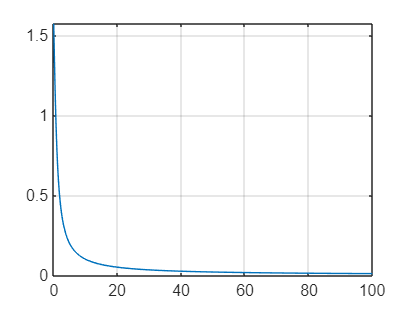

x=sin(t);
L=laplace(x/t,s);
fplot(L,[0 100])
grid on


syms u
X=laplace(x,u);
R=int(X,u,s,inf);
fplot(R,[0 100])
grid on

### Diferenciação no domínio do tempo


$$L\;\left\lbrace \frac{\textrm{dx}\left(t\right)}{\textrm{dt}}\right\rbrace =s\;X\left(s\right)-x\left(0\right)$$



$$L\;\left\lbrace \frac{d^n x\left(t\right)}{{\textrm{dt}}^n }\right\rbrace =s\;L\;\left\lbrace \frac{d^{n-1} x\left(t\right)}{{\textrm{dt}}^{n-1} }\right\rbrace -x^{\left(n-1\right)} \left(0\right)$$


**Exercício 10: **Considere o sinal $x\left(t\right)=\cos \left(t\right)$, $x\left(0\right)=1$

x=cos(t);
L=diff(x,t);
Left=laplace(L,s)

$$Left = -\frac{1}{s^{2}+1}$$


X=laplace(x);
x0=1;
R=s*X-x0;
Right=simplify(R)

$$Right = -\frac{1}{s^{2}+1}$$

### Integração no domínio do tempo


$$L\left\lbrace \int_{-\infty \;}^t x\left(\tau \;\right)d\tau \;\right\rbrace =\frac{X\left(s\right)}{s}+\frac{\int_{-\infty \;}^0 x\left(\tau \;\right)d\tau \;}{s}$$


**Exercício 11: **Considere o sinal $x\left(t\right)=e^{3t}$

syms tau
x=exp(3*tau);
le=int(x,tau,-inf,t);
Left=laplace(le,s)

$$Left = \frac{1}{3\,\left(s-3\right)}$$


X=laplace(x,s);
xr=int(x,tau,-inf,0);
Right=simplify(X/s+xr/s)

$$Right = \frac{1}{3\,\left(s-3\right)}$$

### Teorema do valor final


$$\lim_{t\longrightarrow \infty \;} \;x\left(t\right)=\lim_{s\longrightarrow 0} \;s\;X\left(s\right)$$


**Exercício 12: **Considere o sinal $x\left(t\right)=\left(1-e^{-t} \right)u\left(t\right)$

x=(1-exp(-t));
limit(x,t,inf)

$$ans = 1$$


X=laplace(x,s);
limit(s*X,s,0)

$$ans = 1$$

## Expansão em frações parciais

$X\left(s\right)=\frac{B\left(s\right)}{A\left(s\right)}=\frac{b_m s^m +b_{m-1} s^{m-1} +\cdots +b_1 s+b_0 }{a_n s^n +a_{n-1} s^{n-1} +\cdots +a_1 s+a_0 }$, $m<n$

supondo que $\lambda_i$ são as raízes de $A\left(s\right)$

- Se as raízes forem distintas $A\left(s\right)=a_n \Pi_{i=1}^n s-\lambda_i$

                            
$$X\left(s\right)=\frac{c_1 }{s-\lambda_1 }+\frac{c_2 }{s-\lambda_2 }+\cdots +\frac{c_n }{s-\lambda_n }$$


            e os coeficientes são calculados como

                            
$$c_i =\lim_{s\longrightarrow \lambda_i } \left(s-\lambda_i \right)X\left(s\right)$$


            ou 

                            
$$c_i ={\left\lbrack \left(s-\lambda_i \right)X\left(s\right)\right\rbrack }_{s=\lambda_i }$$


**Exercício 13: **Expresse em frações parciais o sistema dado por 


$$X\left(s\right)=\frac{s^2 +3s+1}{s^3 +5s^2 +2s-8}$$


A=[1 5 2 -8];
r=roots(A);

syms s
X=(s^2+3*s+1)/(s^3+5*s^2+2*s-8);
c1=limit((s-r(1))*X,s,r(1))

$$c1 = \frac{1}{2}$$

c2=limit((s-r(2))*X,s,r(2))

$$c2 = \frac{1}{6}$$

c3=limit((s-r(3))*X,s,r(3))

$$c3 = \frac{1}{3}$$


X1=simplify((s-r(1))*X)

$$X1 = \frac{s^{2}+3\,s+1}{s^{2}+s-2}$$

X2=simplify((s-r(2))*X)

$$X2 = \frac{s^{2}+3\,s+1}{s^{2}+3\,s-4}$$

X3=simplify((s-r(3))*X)

$$X3 = \frac{s^{2}+3\,s+1}{s^{2}+6\,s+8}$$


c1=subs(X1,s,r(1))

$$c1 = \frac{1}{2}$$

c2=subs(X2,s,r(2))

$$c2 = \frac{1}{6}$$

c3=subs(X3,s,r(3))

$$c3 = \frac{1}{3}$$

### Comando residue


$$X\left(s\right)=\frac{r_1 }{s-p_1 }+\frac{r_2 }{s-p_2 }+\cdots +\frac{r_n }{s-p_n }+K$$


$R=\left\lbrack r_1 \;r_2 \;r_3 \cdots r_n \right\rbrack$, $P=\left\lbrack p_1 \;p_2 \;p_3 \cdots p_n \right\rbrack$ e $K$é o resíduo da divisão dos dois polinômios.

**Exercício 14: **Expresse em frações parciais por meio do comando `residue`, o sistema dado por 


$$X\left(s\right)=\frac{s^2 +3s+1}{s^3 +5s^2 +2s-8}$$


num=[1 3 1 10];
den=[1 5 2 -8];
[R,P,K]=residue(num,den)

R =    -1.0000
   -2.0000
    1.0000


P =    -4.0000
   -2.0000
    1.0000


K = 1